In loc sa evaluam **y = f(x) **in punctele date, evaluare care poate genera probleme atunci cand curbele au **segmente verticale sau cicluri**, curba splie cubica parametrica interpoleaza ambele dimensiuni folosind un parametru comun **t**.

Curba spline cubica parametrica are forma: $\vec{r}(t) = \left( x(t),\ y(t) \right), \quad t \in [t_0, t_n]$

## Control points at t parameter

n = 5;

px = randn(1, n) * 10;
py = randn(1, n) * 5;

t = linspace(0, 1, length(px));

## Constructing the parametric splines

Sx = spline_natural(t, px);
Sy = spline_natural(t, py);

## Evaluating the splines

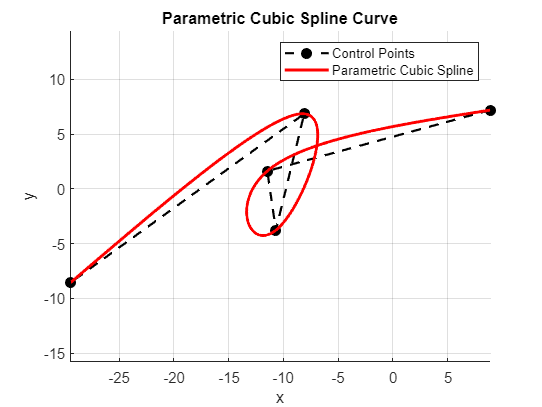

tt = linspace(t(1), t(end), 1000);
xx = Sx(tt);
yy = Sy(tt);

figure;
hold on;
plot(px, py, 'ko--', 'LineWidth', 1.5, 'MarkerFaceColor', 'k', 'DisplayName', 'Control points');
plot(xx, yy, 'r-', 'LineWidth', 2, 'DisplayName', 'Evaluate points by the Spline');
legend('Control Points', 'Parametric Cubic Spline');
axis equal;
xlabel('x'); ylabel('y');
title('Parametric Cubic Spline Curve');
grid on;